# 1201第十四周第十三次上机实验

**1.** 新建一个名为addup.m的脚本，在该脚本中，计算等式1+2+3+4的加和结果并输出。

**2. **利用`MATLAB`编程，在`1-50`之内找出所有能够被`7`整除的数字。

ret = [];
for i = 1:50
    if mod(i,7) == 0
        ret = [ret,i];
    end
end
disp(ret);

  列 1 至 6

     7    14    21    28    35    42

  列 7

    49



**3.**使用while循环，在1~30之间寻找数字25，找到后立即退出循环

cur_num = 1

cur_num = 1

while 1
    if cur_num == 25
        break
    end
    cur_num = cur_num + 1;
end
disp(cur_num);

    25



**4.**

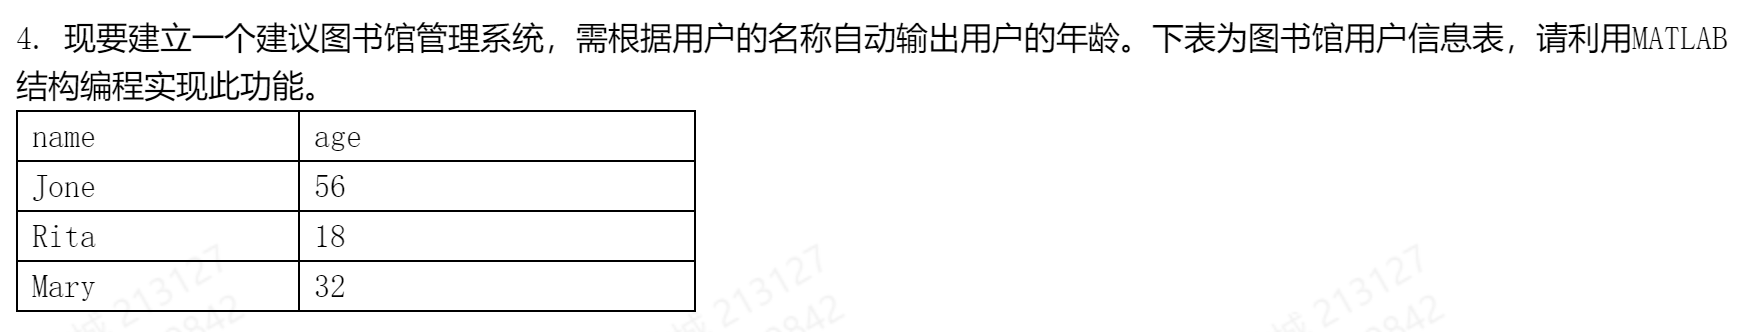

s = struct('Jone',56,'Rita',18,'Mary',32);
disp(s);

    Jone: 56
    Rita: 18
    Mary: 32



disp(s.Jone);

    56



disp(s.Rita);

    18



disp(s.Mary);

    32



**5.** 试举例总结`MATLAB`中“`break`”，“`continue`”，“`return`”三种用法功能的区别。

% break
% 跳出本层循环
% continue 
% 跳过本次循环，但不跳出循环
% return
% 1.将控制权返回给键盘
% 2.将控制权返回给调用函数

**6. **小明有`100`元去购买水果，已知苹果`2`元`/`斤，香蕉`3`元`/`斤，葡萄`6`元`/`斤，每种水果必须都要购买且`100`元必须全部花完。试用`MATLAB`求解所有的购买方案。

ret = []


ret =

     []



for apple = 1:50
    for banana = 1:34
        for grape = 1:17
            if 2*apple+3*banana+6*grape == 100
                ret = [ret;[apple,banana,grape]];
            end
        end
    end
end
disp(length(ret));

   120



disp(ret);

     2     2    15
     2     4    14
     2     6    13
     2     8    12
     2    10    11
     2    12    10
     2    14     9
     2    16     8
     2    18     7
     2    20     6
     2    22     5
     2    24     4
     2    26     3
     2    28     2
     2    30     1
     5     2    14
     5     4    13
     5     6    12
     5     8    11
     5    10    10
     5    12     9
     5    14     8
     5    16     7
     5    18     6
     5    20     5
     5    22     4
     5    24     3
     5    26     2
     5    28     1
     8     2    13
     8     4    12
     8     6    11
     8     8    10
     8    10     9
     8    12     8
     8    14     7
     8    16     6
     8    18     5
     8    20     4
     8    22     3
     8    24     2
     8    26     1
    11     2    12
    11     4    11
    11     6    10
    11     8     9
    11    10     8
    11    12     7
    11    14     6
    11    16     5
    11    18     4
    11    20     3
    11    22

**7. **试用`MATLAB`编程实现以下功能：求`下x^2-3x+2`在[0.1, 3]之内所有的解，`x`的步长为`0.1`。要求分别使用`for`循环以及矩阵运算的方式完成上述功能，并保存为“`.m`”格式的文件

root = [];
for x=0.1:0.1:3
    if x.^2-3*x+2==0
        root = [root,x];
    end
end
disp(root);

     1     2



**8.**已知`fibonccci`数组中各个元素满足如下关系：a_k+2 = a_k+a_k+1，且a_1=a_2`=1`，求`fibonccci`数组中第一个大于`100`的元素及对应的序列号

iterator = 3;
fib_list = [1,1];
ret = 0;
while 1
    fib_list(iterator) = fib_list(iterator-1)+fib_list(iterator-2);
    if fib_list(iterator)>100
        ret = fib_list(iterator);
        break;
    else
        iterator = iterator + 1;
    end
end
disp(ret);

   144



disp(iterator);

    12



**9. **定义回文数为正读和反读都一样的数字，如`1221`。试利用`MATLAB`求解`1000-9999`内所有的回文数

ret = [];
for i = 1000:9999
    str = num2str(i);
    str2 = reverse(str);
    if str == str2
        ret = [ret,i];
    end
end
disp(ret);

  列 1 至 3

        1001        1111        1221

  列 4 至 6

        1331        1441        1551

  列 7 至 9

        1661        1771        1881

  列 10 至 12

        1991        2002        2112

  列 13 至 15

        2222        2332        2442

  列 16 至 18

        2552        2662        2772

  列 19 至 21

        2882        2992        3003

  列 22 至 24

        3113        3223        3333

  列 25 至 27

        3443        3553        3663

  列 28 至 30

        3773        3883        3993

  列 31 至 33

        4004        4114        4224

  列 34 至 36

        4334        4444        4554

  列 37 至 39

        4664        4774        4884

  列 40 至 42

        4994        5005        5115

  列 43 至 45

        5225        5335        5445

  列 46 至 48

        5555        5665        5775

  列 49 至 51

        5885        5995        6006

  列 52 至 54

        6116        6226        6336

  列 55 至 57

        6446        6556        6666

  列 58 至 60

        6776        6886

**10.**试找出文件`codes.m`中代码的行数，不包括空白行以及注释行（提示：使用循环中的`continue`实现功能）

(题目文档见课堂发送的word文件)

clear
clc
re=int16(zeros(1e6,23));  %预定义矩阵,加快速度
fid=fopen('code.m');  %打开文本文件
INDEX=0;
iterator = 0;
while ~feof(fid)
   str = fgetl(fid);
   if length(str) == 0
       continue;
   end
   if str(1) == '%' % 代表本行是注释行
       continue;
   end
   iterator = iterator + 1;
end
fclose(fid);
disp("本文一共有有效行:");

本文一共有有效行:


disp(iterator);

     3

